clear
load('./traces_v4/input_sets_second_op_31.mat');
numberOfSets = 1000;
setSize = 31;

%Get the mean traces by sets of 31
meanTraces = getMeanTraces(traces_Y,numberOfSets,setSize)

meanTraces =     0.0014    0.0014    0.0016    0.0015    0.0015    0.0015    0.0015    0.0014    0.0013    0.0013    0.0012    0.0012    0.0013    0.0014    0.0014    0.0014    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0010    0.0009    0.0006    0.0005    0.0004    0.0003    0.0002    0.0000   -0.0001   -0.0004   -0.0008   -0.0012   -0.0017   -0.0023   -0.0028   -0.0032   -0.0036   -0.0040   -0.0043   -0.0046   -0.0048   -0.0051   -0.0052   -0.0053   -0.0052   -0.0051   -0.0049
    0.0018    0.0018    0.0018    0.0017    0.0016    0.0015    0.0015    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0019    0.0019    0.0020    0.0019    0.0018    0.0016    0.0015    0.0012    0.0011    0.0010    0.0008    0.0006    0.0004    0.0000   -0.0005   -0.0010   -0.0014   -0.0018   -0.0022   -0.0025   -0.0028   -0.0033   -0.0037   -0.0041   -0.0044   -0.0046   -0.0047   -0.0049   -0.0049   -0.0049   -0.

% Vectors for the ROC curve:
falsePositiveRates = zeros(1,16);
truePositiveRates = zeros(1,16);
index = 0;

## **Correlation**

threshold =  0.993937992840583;
%Mean traces
[confusionMatrix,type1Errors, type2Errors] = getConfusionMatrixCorr(meanTraces,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

%Calculate accuracy, false positives, false negatives
confusionMatrix

confusionMatrix =        54399       12445
      261144      171512


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6036

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.1862

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4523

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

freq = 100e6;
samplesPerSec = 40e9;
samplesPerCycle = samplesPerSec/freq

samplesPerCycle = 400

compressTraceSize = ceil(size(traces_Y,2)/samplesPerCycle)

compressTraceSize = 51

% Try using the max by clock cycle after doing the average
compressTraces1 = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.994115619791091;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces1,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        44864       21980
      258493      174163


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5975

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3288

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4385

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average
compressTraces2 = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.993485561123956;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces2,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        47520       19324
      249849      182807


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5775

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.2891

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4611

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces
compressTraces3 = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces3 = getMeanTraces(compressTraces3,numberOfSets,setSize);
threshold = 0.994840621160766;

confusionMatrix = getConfusionMatrixCorr(compressTraces3,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        46233       20611
      262504      170152


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6067

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3083

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4332

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces4 = compressAvgWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
% compressTraces4 = getMeanTraces(compressTraces4,numberOfSets,setSize);
% threshold = 0.993485561123956;
% 
% 
% confusionMatrix = getConfusionMatrixCorr(compressTraces4,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

clockIndexes = getClockIndexes();

% Try using the max by clock cycle but sync after doing the average
compressTraces5 = compressMaxWithSync(meanTraces,clockIndexes);
threshold = 0.9942;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces5,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        43739       23105
      253636      179020


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5862

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3457

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4460

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average but sync'ed
compressTraces6 = compressAvgWithSync(meanTraces,clockIndexes);
threshold = 0.9938;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixCorr(compressTraces6,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        43608       23236
      239184      193472


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5528

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3476

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4746

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces but sync'ed
compressTraces7 = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces7 = getMeanTraces(compressTraces7,numberOfSets,setSize);
threshold = 0.9952;

confusionMatrix = getConfusionMatrixCorr(compressTraces7,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        44830       22014
      260656      172000


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.6025

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3293

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4341

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces8 = compressAvgWithSync(traces_Y,clockIndexes);
% compressTraces8 = getMeanTraces(compressTraces8,numberOfSets,setSize);
% threshold = 0.9938;
% 
% 
% confusionMatrix = getConfusionMatrixCorr(compressTraces8,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

compressTraces9 = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces9 = getMeanTraces(compressTraces9,numberOfSets,setSize);
threshold = 0.9932;


confusionMatrix = getConfusionMatrixCorr(compressTraces9,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        45555       21289
      249780      182876


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5773

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3185

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.4573

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

## **Euclidean distance:**

%With mean traces 
threshold = 0.0569;

confusionMatrix = getConfusionMatrixDist(meanTraces,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        38345       28499
      177287      255369


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.4098

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.4264

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5880

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the max by clock cycle after doing the average
compressTraces1 = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 0.0044;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces1,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        43566       23278
      222815      209841


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5150

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3482

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5073

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average
compressTraces2 = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
threshold = 8.6954e-04;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces2,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        25271       41573
      127694      304962


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.2951

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.6219

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.6611

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces
compressTraces3 = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces3 = getMeanTraces(compressTraces3,numberOfSets,setSize);
threshold = 0.0042;

confusionMatrix = getConfusionMatrixDist(compressTraces3,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        43582       23262
      222473      210183


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5142

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3480

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5080

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces4 = compressAvgWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
% compressTraces4 = getMeanTraces(compressTraces4,numberOfSets,setSize);
% threshold = 8.6954e-04;
% 
% 
% confusionMatrix = getConfusionMatrixDist(compressTraces4,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

% Try using the max by clock cycle but sync after doing the average
compressTraces5 = compressMaxWithSync(meanTraces,clockIndexes);
threshold = 0.0044;

%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces5,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
confusionMatrix

confusionMatrix =        43213       23631
      220975      211681


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5107

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3535

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5103

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% Try using the average by clock cycle after doing the average but sync'ed
compressTraces6 = compressAvgWithSync(meanTraces,clockIndexes);
threshold = 8.4867e-04;
%Calculate accuracy, false positives, false negatives
confusionMatrix = getConfusionMatrixDist(compressTraces6,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        24926       41918
      127662      304994


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.2951

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.6271

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.6605

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

%Max per clock in original traces but sync'ed
compressTraces7 = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces7 = getMeanTraces(compressTraces7,numberOfSets,setSize);
threshold = 0.0042;

confusionMatrix = getConfusionMatrixDist(compressTraces7,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        43471       23373
      221711      210945


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5124

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3497

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5093

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

% compressTraces8 = compressAvgWithSync(traces_Y,clockIndexes);
% compressTraces8 = getMeanTraces(compressTraces8,numberOfSets,setSize);
% threshold = 8.4867e-04;
% 
% 
% confusionMatrix = getConfusionMatrixDist(compressTraces8,inputs_b(1:setSize:size(inputs_b,1),:),threshold);
% 
% confusionMatrix
% comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
% falsePosRate = getFalsePositiveRate(confusionMatrix)
% falseNegRate = getFalseNegativeRate(confusionMatrix)
% accuracy = getAccuracy(confusionMatrix)

compressTraces9 = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces9 = getMeanTraces(compressTraces9,numberOfSets,setSize);
threshold = 0.0042;


confusionMatrix = getConfusionMatrixDist(compressTraces9,inputs_b(1:setSize:size(inputs_b,1),:),threshold);

confusionMatrix

confusionMatrix =        44377       22467
      219401      213255


comparisons = confusionMatrix(1,1) + confusionMatrix(1,2) + confusionMatrix(2,1) + confusionMatrix(2,2);
falsePosRate = getFalsePositiveRate(confusionMatrix)

falsePosRate = 0.5071

falseNegRate = getFalseNegativeRate(confusionMatrix)

falseNegRate = 0.3361

accuracy = getAccuracy(confusionMatrix)

accuracy = 0.5158

index = index + 1;
falsePositiveRates(index) = falsePosRate;
truePositiveRates(index) = 1 - falseNegRate;

Plot the ROC curve

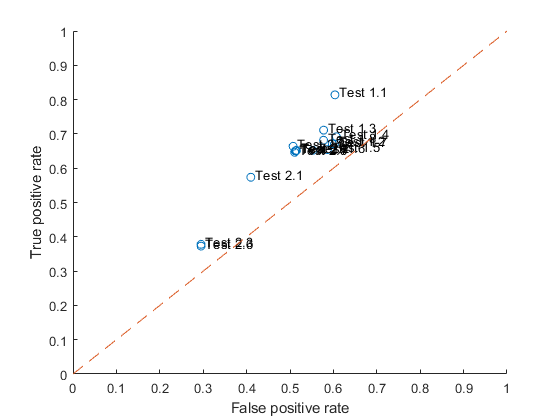

scatter(falsePositiveRates,truePositiveRates);
str = ["Test 1.1" "Test 1.2" "Test 1.3" "Test 1.4" "Test 1.5" "Test 1.6" "Test 1.7" "Test 1.8" "Test 2.1" "Test 2.2" "Test 2.3" "Test 2.4" "Test 2.5" "Test 2.6" "Test 2.7" "Test 2.8"];
str = cellstr(str);
dx = 0.01; dy = 0.01;
text(falsePositiveRates+dx,truePositiveRates+dy,str)
hold on 
plot(0:1,0:1,'--')
hold off
xlabel('False positive rate')
ylabel('True positive rate')

Bounded collision detection criterion ?

% colDet = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     colDet(i) = bcdc(meanTraces(1,:),meanTraces(i,:));
% end
% plot(colDet)
% grid on
% line([0 110],[max(colDet(1:10)) max(colDet(1:10))],'Color','red','LineStyle','--')
% %Calculate accuracy, false positives, false negatives
% maxDet = max(colDet(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (colDet(i)<=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (colDet(i)>=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Use the filtered signal

% %Get the mean traces by sets of 50
% meanTraces2 = zeros(numberOfSets,size(traces_filt,2));
% 
% for i = 1 : numberOfSets
%     meanTraces2(i,:)=mean(traces_filt((i-1)*setSize+1:i*setSize,:),1);
% end

%Calculate euclidean distance with respect to the first average set trace
% euclidDistances2 = zeros(1,numberOfSets);
% 
% for i = 1 : numberOfSets
%     euclidDistances2(i) = norm(meanTraces2(1,:)-meanTraces2(i,:));
% end
% plot(euclidDistances2)
% grid on
% hold on
% plot(euclidDistances)
% line([0 110],[max(euclidDistances2(1:10)) max(euclidDistances2(1:10))],'Color','red','LineStyle','--')
% hold off
% grid on
% 
% %Calculate accuracy, false positives, false negatives
% maxDist = max(euclidDistances2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (euclidDistances2(i)<=maxDist)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (euclidDistances2(i)>=maxDist)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Correlation ?

% corrs2 = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     corr = corrcoef(meanTraces2(1,:),meanTraces2(i,:));
%     corrs2(i) = corr(1,2);
% end
% plot(corrs2)
% hold on 
% plot(corrs)
% line([0 110],[min(corrs2(1:10)) min(corrs2(1:10))],'Color','red','LineStyle','--')
% hold off
% grid on
% %Calculate accuracy, false positives, false negatives
% minCorr = min(corrs2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (corrs2(i)>=minCorr)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (corrs2(i)<=minCorr)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

Bounded collision detection criterion ?

% colDet2 = zeros(1,numberOfSets);
% for i = 1 : numberOfSets
%     colDet2(i) = bcdc(meanTraces2(1,:),meanTraces2(i,:));
% end
% plot(colDet2)
% grid on
% hold on 
% plot(colDet)
% line([0 110],[max(colDet2(1:10)) max(colDet2(1:10))],'Color','red','LineStyle','--')
% hold off
% %Calculate accuracy, false positives, false negatives
% maxDet = max(colDet2(1:10));
% falsePos = 0;
% falseNeg = 0;
% for i = 11 : numberOfSets
%     if (colDet2(i)<=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
%             falsePos = falsePos +1;
%         end
%     end
% end
% falsePos
% falsePosRate = falsePos / (numberOfSets - 10) *100
% for i = 11 : numberOfSets
%     if (colDet2(i)>=maxDet)
%         if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
%             falseNeg = falseNeg +1;
%         end
%     end
% end
% falseNeg
% falseNegRate = falseNeg / (numberOfSets - 10) * 100
% 
% accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100